### **一、TTB-RPA河流纵剖面分析程序**：

（1）程序开发人员：戴钊龙，王一舟（待定），沈言根，李安波

（2）本函数集将 TopoToolBox 开源库集成到 RiverProAnalysis（王一舟等，2022） 程序内，避免了原始 RiverProAnalysis程序需要通过Arcgis软件进行数据预处理。此外，基于程序流程化运行原则提供了运行案例，简化了手动操作。

（3）如果使用了程序，请引用以下文献：  

        [1] 王一舟, 郑德文, 张会平, 2022. 河流高程剖面分析的方法与程序实现——基于Matlab平台编写的开源函数集RiverProAnalysis. 中国科学:地球科学 52, 2039–2060.

        [2]  Schwanghart, W., Kuhn, N.J., 2010. TopoToolbox: A set of Matlab functions for topographic analysis. Environmental Modelling & Software 25.

        [3]   Schwanghart, W., Scherler, D., 2014. Short Communication: TopoToolbox 2 – MATLAB-based software for topographic analysis and modeling in Earth surface sciences. Earth Surface Dynamics 2, 1–7.

（4）如果使用该程序遇到问题需要反馈，可参考Bilibili视频。。。，或通过邮件方式联系yangen_shen@163.com

### **二、使用教程**：

在运行函数之前, 需要准备研究区DEM数据。使用函数 ttb_`export_selected_basins 提取合适的流域为此处的DEM文件路径进行分析。`

`其中：RPA_with_TTB 为单流域分析，RPA_with_TTB_multi 为多流域分析。`

如果流域之间的差别不大，可以使用 RPA_with_TTB_multi 一次性处理结束。输出的内容两者并无差别。

> 注意：建议按照分节符一节一节运行，以便出现错误的时候及时发现。

### **三、数据输入输出**：

- dem_path：                    DEM 文件路径，要求为流域DEM

- output_workspace：       输出文件路径

- threshold：                     启动河流所需的最小上游区域（单位为像素）

- len_win：                        局部河段长度, 即以此分割河道, 每一段的各个节点被赋予相同的陡峭指数

- K：                                  河流侵蚀系数，可以包含多个

clear;
clc;

% 输出文件路径（注意后面有个'\'表示是个文件夹）
output_workspace = "assets\TaiHang\result\basins\basin_27\";
% DEM 文件路径
dem_path = 'assets\TaiHang\result\basins\basin_27\basin_27.tif';
% 提取河流所需的最小阈值（单位为DEM内像素个数）
threshold = 2000;  
% 局部河段长度
len_win = 200;
% 侵蚀系数
K1 = 1e-6; 
K2 = 1.5e-6; 
K3 = 2e-6;
K = [K1, K2, K3];

### **四、计算参考凹度**

**步骤如下**：

- 基础数据分析；

- 获取出水口坐标；

- 搜索河流源头；

- 计算河流剖面信息；

- 计算使得高程误差最小的凹度；

- 统计所有流域的最小误差凹度求均值为参考凹度。

#### **（1）基础数据分析**

% 加载 DEM 并进行填洼、高斯滤波
dem = fillsinks(GRIDobj(dem_path));
dem.Z = imgaussfilt(dem.Z, 2);

% 计算流向、流量并提取河网二值栅格图
flow_direction = FLOWobj(dem);
flow_accumulation = flowacc(flow_direction);

stream = STREAMobj(flow_direction, 'minarea', threshold);
main_stream = trunk(stream);

% 干流对应的坡度与面积
area  = getnal(stream, flow_accumulation) * dem.cellsize ^ 2; % 单位：m
slope = gradient(stream, dem); % [0, 1]
main_stream_area = getnal(main_stream, flow_accumulation) * dem.cellsize ^ 2; % 单位：m
main_stream_slope = gradient(main_stream, dem); % [0, 1]
distance = main_stream.distance ./ 1000; % 单位：km

% 转换为 RiverProAnalysis所需的类型
elevation_grid = double(dem.Z);
flow_direction_grid = double(flow_direction.FLOWobj2GRIDobj().Z);
flow_accumulation_grid = flow_accumulation.Z;
corner = [dem.size(1) 1 1] * dem.refmat;
xllcorner = corner(1);
yllcorner = corner(2);
cellsize = dem.refmat(2, 1);
ac = threshold * cellsize * cellsize;

#### **（2）获取出水口坐标**

    出水口是指水流离开汇水区的点，这个点可以认为汇水区边界上的最低点。 通常一条河流的汇水区没有其他的地表径流流入且只有惟一的一个出水点。因此，我们可以通过流域的DEM进行水文分析得到河网，提取河网栅格的高程数据，找到这部分高程中的最低点，即为我们所需的出水口点。

> 注意：我们需要观察一下这里的出水口流量是否会过小，过小可能说明设置的阈值 threshold 过大。

% 通过自定义的函数获取出水口坐标
[outlet_x, outlet_y] = ttb_search_outlet_coordinate(dem, flow_accumulation, threshold, 1);

出水口的二维矩阵下标为：(379, 368) 
出水口的地理坐标为：(634451.057722, 4223513.041991) 
出水口的高程为：995.443115 
出水口的流量为：110938.000000

#### **（3）搜索河流源头**

    函数 `Search_WaterHead` 的主要功能是根据流量累积矩阵 (`FlowAcc`) 和流向矩阵 (`FlowDir`)，在给定的汇水区面积阈值 (`Ac`) 的条件下，搜索并确定流域内的水头位置，然后将这些水头的地理坐标保存到指定的文件中。

    这个函数的目的是在流域内找到水头位置，水头是指汇水区域内不能再接收更多水流的栅格（所有流入栅格均为小于 `Ac` 的栅格）。在搜索的过程中，函数根据流量累积和流向信息进行递归判断，并将水头结果以地理坐标的形式保存到指定文件。

**输入参数**：

- `FlowAcc`: 流量累积矩阵，描述每个栅格积累了多少水。

- `FlowDir`: 流向矩阵，定义水流从一个栅格流向另一个栅格的方向。

- `LeftX`, `DownY`: 区域的左下角坐标，用于计算每个栅格的地理位置。

- `cellsize`: 每个栅格的边长。

- `ouletX`, `ouletY`: 出口点的坐标，用于作为水头搜索的起始点。

- `Ac`: 汇水区面积阈值，表示只有当流量累积大于此值时，才能被认为是河流。

- `outputFilePath`: 输出文件路径，用于保存计算出的水头位置。

**输出信息**：

- river_head.txt：该流域的河流源头点XY文本数据

% 通过RiverProAnalysis获取源头点
river_head_path = strcat(output_workspace, "river_head.txt");
Search_WaterHead(flow_accumulation_grid, flow_direction_grid, xllcorner, yllcorner, ...
    cellsize, outlet_x, outlet_y, ac, river_head_path);

% 加载前面得到的河流源头数据
river_head = load(river_head_path);
river_head_x = river_head(:, 1);
river_head_y = river_head(:, 2);

#### （4）进行可视化

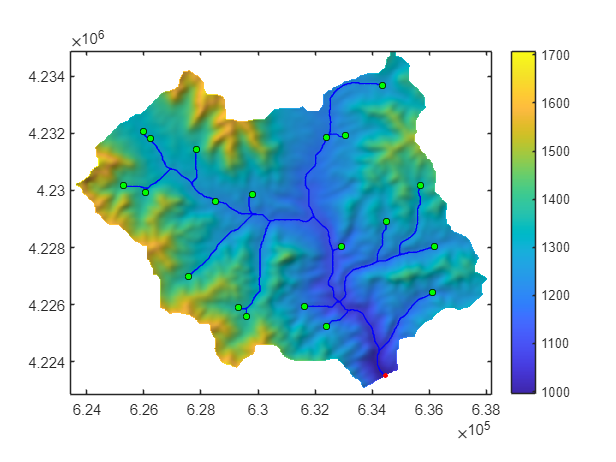

% 可视化河流和出水口点 此处可以观察河网、出水口以及源头点位置是否正常
figure;
imageschs(dem);
hold on;
plot(stream, 'LineWidth', 1, 'Color', 'b');
plot(outlet_x, outlet_y, 'Marker',  '.', 'MarkerSize', 10, 'Color', 'r');
scatter(river_head_x, river_head_y, 20, 'g', 'filled', 'MarkerEdgeColor', 'k');
hold off;

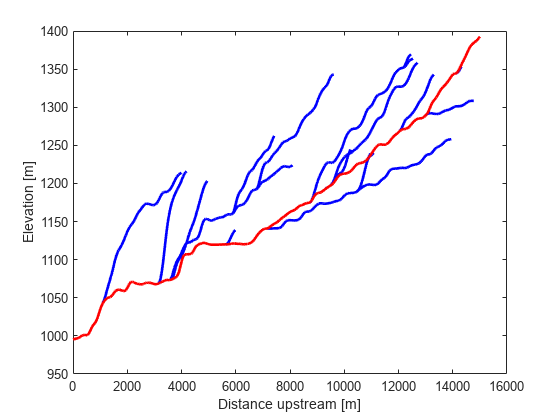

% 剖面图
figure;
plotdz(stream, dem, 'LineWidth', 2, 'Color', 'b');
hold on;
plotdz(trunk(stream), dem, 'LineWidth', 2, 'Color', 'r');
hold off;

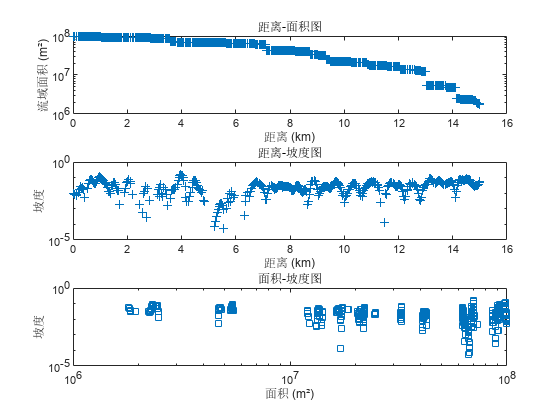

% 其他图
figure;

% 绘制距离-面积图
subplot(3, 1, 1);
semilogy(distance, main_stream_area, '+'); % 使用对数坐标
xlabel('距离 (km)');
ylabel('流域面积 (m²)');
title('距离-面积图');

% 绘制距离-坡度图
subplot(3, 1, 2);
semilogy(distance, main_stream_slope, '+');
xlabel('距离 (km)');
ylabel('坡度');
title('距离-坡度图');

% 绘制坡度-面积图
subplot(3, 1, 3);
loglog(main_stream_area, main_stream_slope, 'square');
% slopearea(main_stream, dem, flow_accumulation);
xlabel('面积 (m²)');
ylabel('坡度');
title('面积-坡度图');

#### **（5）计算河流剖面信息**

`RiverProInfo` 函数用于从数字高程模型 (DEM) 数据中提取河流纵剖面信息。

**文件输出**: 每条河流生成一个 `.txt` 文件，命名为 `profile_<编号>.txt`，包含剖面信息：

- 第1列: 平面 Y 坐标（上边界 - 当前行号 × 栅格大小）。

- 第2列: 平面 X 坐标（左边界 + 当前列号 × 栅格大小）。

- 第3列: 溯源距离（从河流起点到当前点的距离，单位：米）。

- 第4列: 高程（单位：米）。

- 第5列: 汇水方向。

- 第6列: 汇水面积（单位：平方米）。

- 第7列: Chi 距离（单位：无）。

% 根据河道源头计算河流剖面信息，输出到profile中(profile\文件夹由RiverProInfo函数创建)
profile_workspace = strcat(output_workspace, "profile\");
if exist(profile_workspace, "dir")
    rmdir(profile_workspace, 's');
end
RiverProInfo(elevation_grid, flow_direction_grid, flow_accumulation_grid, ...
            cellsize, river_head_x, river_head_y, xllcorner, yllcorner, ...
            0.01, 0.45, profile_workspace);

#### **（6）计算使得高程误差最小的凹度**

`    Theta_FitChiplot` 是基于 Mudd et al. (2018) 方法实现的，用于计算最佳凹度指数 θ 。通过将河流的 chi-z 关系拟合成直线，该函数寻找使高程偏差（Elevation scatter）最小的凹度值，从而确定最优 θ。

- 绘制 θ-高程偏差图，标记最优 θ。

- 保存最优 θ 和最小偏差值到文件 theta-min_Scatter_rather.txt 中。

        在同时考虑多个流域时，可进一步考虑使得所有流域偏差值最小的凹度。

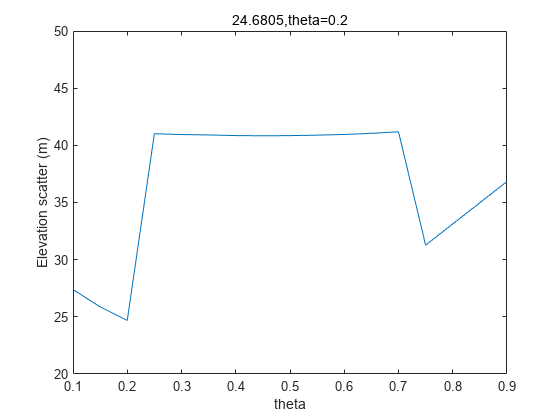

% 读取profile的文件数
profile_num = length(dir(strcat(profile_workspace, "*.txt")));
% 寻找最佳的参考凹度，输出到workspace的figure.jpg和theta-min_Scatter_rather.txt中
min_misfit_theta = Theta_FitChiplot(profile_workspace, profile_num);

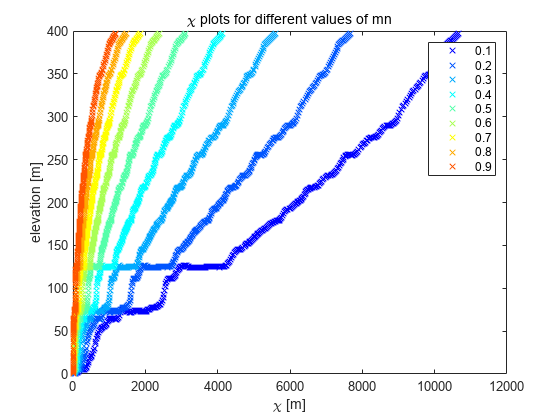

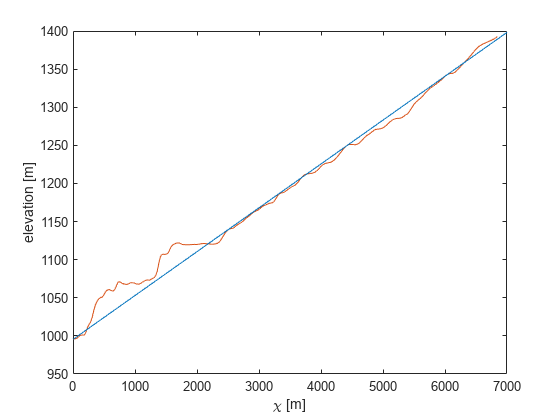

% 输出 ttb 的mnplot
chiplot(main_stream, dem, flow_accumulation, 'mnplot', true);

fprintf("计算得到的使得误差最小的凹度为：%f", min_misfit_theta);

计算得到的使得误差最小的凹度为：0.200000

reference_concavity = input("请输入想用的参考凹度：");

### **五、获取chi-map和ksn-map**

#### **（1）chi-map**

        在 'RiverProInfo.m' 函数中，我们从源头点开始采用逐点累加的方式来近似计算Chi值，出水口点的Chi值设为 0 ，然后沿着河流路径逐步向上游累加每一段的Chi增量，以此替代积分过程。这种方式在离散数据（如栅格数据）下是常见的近似积分方法。

具体来说，Chi距离的计算方式可以理解为通过数值积分的离散形式来逼近连续积分：


$$\chi (x)=\int_0^x (\frac{A_0 }{A(x^{\prime } )})^{\frac{m}{n}} dx^{\prime }$$


        在代码中，这个积分被离散化为了多个小段的累加，即：


$$\chi_i =\chi_{i-1} +(\frac{A_0 }{A_{i-1} })^{\frac{m}{n}} \Delta l_{i-1,i}$$


其中：

- 每一个点的Chi值 $\chi_i$ 基于前一点的Chi值 $\chi_{i-1}$ 累加一个增量，增量由该段的汇水面积和沿河距离决定。

- $\Delta l_{i-1,i}$ 是两个相邻点之间的流向距离（沿河道长度），而 $\frac{A_0 }{A_{i-1} }$ 的幂次控制了Chi对汇水面积的敏感性。

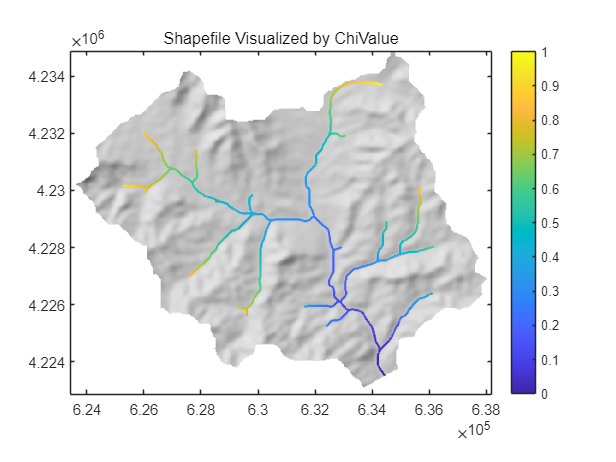

% 输出ChiMap
chi_map = Auto_ChiMap(dem_path, flow_accumulation_grid, flow_direction_grid, xllcorner, yllcorner, ...
    cellsize, outlet_x, outlet_y, ac, reference_concavity, output_workspace);
% 可视化（属性在上面的函数中固定输出为ChiValue）
ttb_visualize_shapefile(dem, strcat(output_workspace, "ChiMap.shp"), 'ChiValue');

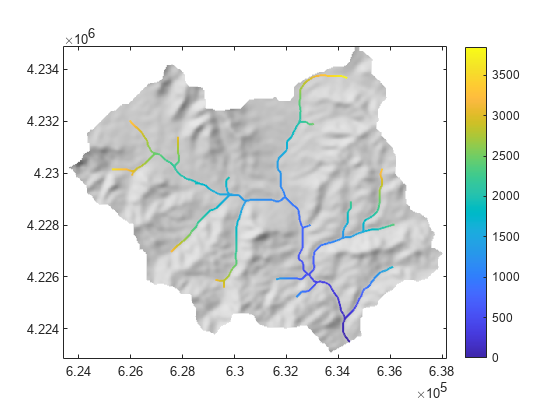

% 展示 ttb 计算得到的chimap
c = chitransform(stream, flow_accumulation, 'mn', reference_concavity);
figure;
imageschs(dem, [], 'colormap', [.9 .9 .9], 'colorbar',false);
hold on;
plotc(stream, c);
colormap(parula(256));
colorbar;
hold off;

#### **（2）ksn-map**

    我们通过以下公式计算ksn：


$$z(x)=z_b +k_{sn} \chi (x)$$


    具体地，在 RiverProAnalysis 函数集中基于计算了 ChiMap 二维矩阵的前提下计算 KsnMap。ChiMap得到了一条所有河道的空间信息、高程信息、Chi值信息等，我们可以通过当前点的高程和 $\chi$ 值使用线性回归得到 $k_{sn}$ 。因此，当我们得到了 ChiMap 后，可以通过 matlab 的 regress 函数输入当前位置的高程和当前位置的 Chi 值做线性回归可以得到 $k_{sn}$ 和 $k_{sn}$ 的误差。

每一段距离限制由 `LenWin` 控制，当该段长度达到 `LenWin` 时，便计算该段的局部陡峭指数。计算的`ksn`值存储在`ksMap`（栅格文件）中，用于生成空间分布图。同时也将`ksn`结果记录到`Sfea_ksnMap`结构体中，随后导出为矢量文件以便进一步分析。

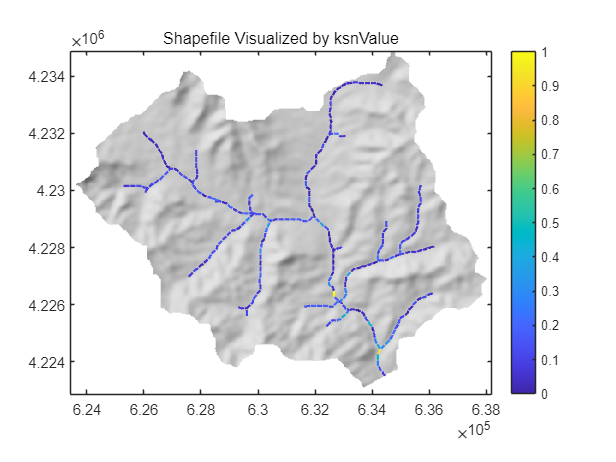

% 输出KsnMap
Auto_ksMap(dem_path, elevation_grid, flow_direction_grid, chi_map, cellsize, ...
    river_head_x, river_head_y, xllcorner, yllcorner, len_win, output_workspace);
% 可视化（属性在上面的函数中固定输出为ksnValue）
ttb_visualize_shapefile(dem, strcat(output_workspace, "ksn.shp"), 'ksnValue');

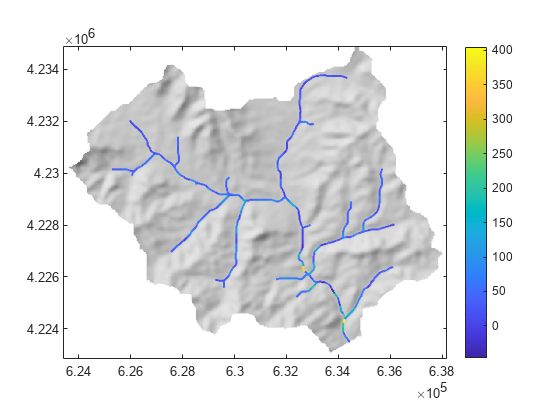

% 展示 ttb 计算得到的ksnmap
ksn = slope ./ (area .^ -reference_concavity);
ksn = aggregate(stream, ksn, 'seglength', len_win);
figure;
imageschs(dem, [], 'colormap', [.9 .9 .9], 'colorbar',false);
hold on;
plotc(stream, ksn);
colormap(parula(256));
colorbar;
hold off;

### **六、构造隆升历史反演**

    隆升历史反演由 RiverProAnalysis 的三个函数协同合作完成。

- LinearUp_MisFit.m

- MainLinearUp_MisFit.m

- linear_uplift_uniformChi.m

    模拟隆升历史需要对河道的 chi-plot 进行微分，而这首先需要选择合适的 chi 值间隔。

    在函数 MainLinearUp_MisFit 中，我们选择了一系列间隔（0.1~10 m）分割所有河道的 chi-plot ，输出到函数 LinearUp_MisFit 中以每个分段 chi-plot 斜率的均值作为这个分段的 $U^*$ ，借助公式：


$$z(0,x)=\int_{-\chi (x)}^0 U^* (t^* )dt^*$$


    正演可以得到平均的河道 chi-plot ，计算其与实际所有河道 chi-plot 的高程偏差，从函数中返回这个偏差后，从所有间隔里面算到的数值里面选择最低偏差对应的 chi 值间隔。然后将这个 chi 值间隔作为参数输入到 linear_uplift_uniformChi 函数中运行。同时，根据无维度的隆升历史计算 $U(t)$ 需要估算侵蚀系数 $K$。

**（1）首先通过选取河流源头点的方式得到自己感兴趣的河道**

请点击选择感兴趣的河流源头点（左键点选选取，Enter结束选取）


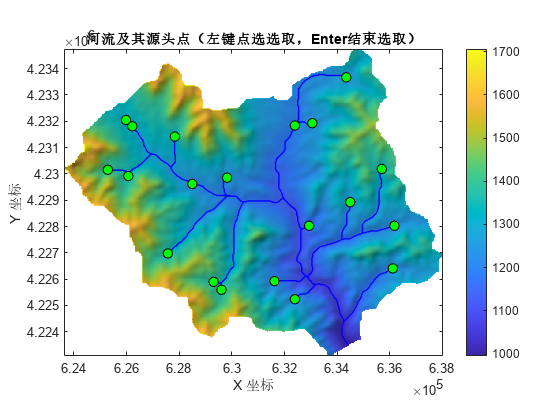

已导出所选河流源头点到文件：assets\TaiHang\result\basins\basin_27\selected_river_head.txt


% 删去前面的河道高程剖面文件
rmdir(profile_workspace, 's');

% 选取感兴趣的河道的源头点
key = input("是否选取感兴趣的河道（yes or no）：", "s");
if strcmp(key, "yes") == 1
    selected_river_head = ttb_export_selected_rivers(output_workspace, dem, stream);
    selected_river_head_x = selected_river_head(:, 1);
    selected_river_head_y = selected_river_head(:, 2);
else
    selected_river_head_x = river_head_x;
    selected_river_head_y = river_head_y;
end  

% 函数RiverProInfo会重新生成一个profile文件并在里面生成相关的剖面信息
RiverProInfo(elevation_grid, flow_direction_grid, flow_accumulation_grid, ...
    cellsize, selected_river_head_x, selected_river_head_y, xllcorner, yllcorner, ...
    0.01, reference_concavity, profile_workspace);

#### **（2）**寻找合适的Chi间距

min_misfit_range = MainLinearUp_MisFit(output_workspace);
% 选取不同chi值间隔的误差plot
fprintf("计算不同的chi值间隔得到的误差最小的chi值为：%f", min_misfit_range);

计算不同的chi值间隔得到的误差最小的chi值为：3.000000

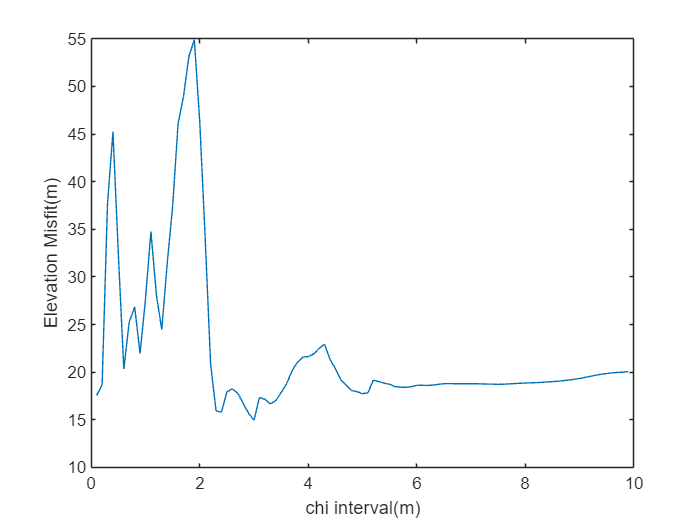

figure;
misfit_chiz_river_data = load(strcat(output_workspace, "MisFit_chiz_river.txt"));
plot(misfit_chiz_river_data(:, 1), misfit_chiz_river_data(:, 2));
xlabel('chi interval(m)');
ylabel('Elevation Misfit(m)');

#### **（3）构造隆生历史反演**

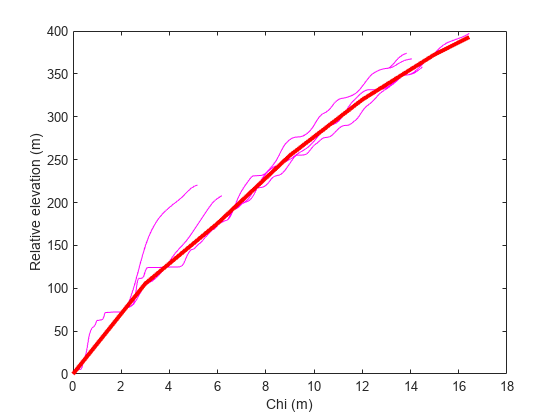

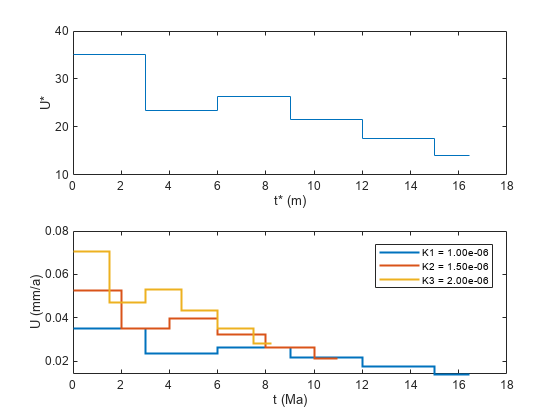

chi_range = input("Input chi values internval：");
linear_uplift_uniformChi(profile_workspace, chi_range, K);